clear;
close all;
clc;

%% 参数设置
n_adc_samples = 256; % number of ADC samples per chirp
chirpLoop = 1;
n_rx=1;
Fs=0.218e6;

% Fs=5e6;             %ADC采样率 
c=3*1e8;            %光速
t_ramp=124*(n_adc_samples+55)/27e6;
% ts=n_adc_samples/Fs;%ADC采样时间
Periodicity=47e-3; %帧周期??
% B_valid =ts*slope;  %有效带宽
% B =3997.56e9;  %有效带宽
B=5000e6; %5000MHz
k=B/t_ramp;    %调频斜率 
fs=1/Periodicity;

fname = ['G:\CODE\FYP_matlab\120GHz0318\47ms\data15', '.bin'];
% fname = ['C:\Users\asd\Desktop\120GHz0318\data4', '.bin'];

    %读取处理后的.bin二进制文件，并以16进制整型写入到RawData矩阵。
fid = fopen(fname, 'r');
RawData = fread(fid, 'int16');
fclose(fid);

fileSize = size(RawData, 1);
%计算chirps数：数据量/天线数/采样点数/2(实部和虚部各占一个数据)。
n_chirps= fileSize/2/n_adc_samples;
%读取所有ComplexData数据并写入数组ComplexData，总维数为：数据量/2(实部和虚部各占一个数据)。
ComplexData = zeros(1, fileSize/2);
IQ_matrix = reshape(RawData,[256,n_chirps*2]);
IQ_matrix=IQ_matrix';%每行256 I一行，Q一行
I_matrix=IQ_matrix(1:2:end,:);
Q_matrix=IQ_matrix(2:2:end,:);
I_chirps=reshape(I_matrix',[1,n_chirps*256]);
Q_chirps=reshape(Q_matrix',[1,n_chirps*256]);
for i=1:1:fileSize/2
    ComplexData(1, i) = I_chirps(i) + 1i*Q_chirps(i);
end
%将数组ComplexData转换成矩阵Chirp_Division，每行数据为1个chirp的数据(含4个天线)，行高为总chirp数。
Chirp_Division = reshape(ComplexData, n_adc_samples*n_rx, n_chirps);
%转置。
Chirp_Division = Chirp_Division.';

%定义Rx_Division为“Rx行，n_chirps*n_adc_samples列”的矩阵,其每行数据为每根天线接受的总数据。
Rx_Division = zeros(n_rx, n_chirps*n_adc_samples);
for row = 1:n_rx
    for i = 1: n_chirps
        Rx_Division(row, (i-1)*n_adc_samples+1:i*n_adc_samples) = Chirp_Division(i, (row-1)*n_adc_samples+1:row*n_adc_samples);
    end
end
    
%将Rx_Division数据按“采样点数，天线，chirp*frame”重排列成Sample_Division，按采样点分离数据。
Sample_Division = reshape(Rx_Division, n_adc_samples, n_rx, n_chirps);
%取第1根天线的采样数据。
Rx_1 = zeros(n_adc_samples, n_chirps);
Rx_1(:) = Sample_Division(:, 1, :);
%时间平均背景减法。
Data1filtOut = zeros(size(Rx_1));
Background = mean(Rx_1, 2);     %返回矩阵每行的平均值。                	
for i=1:n_chirps                                             
    %data1每个值都减去所在行的平均值(background)。
    Data1filtOut(:, i) = Rx_1(:, i) - Background;    
end

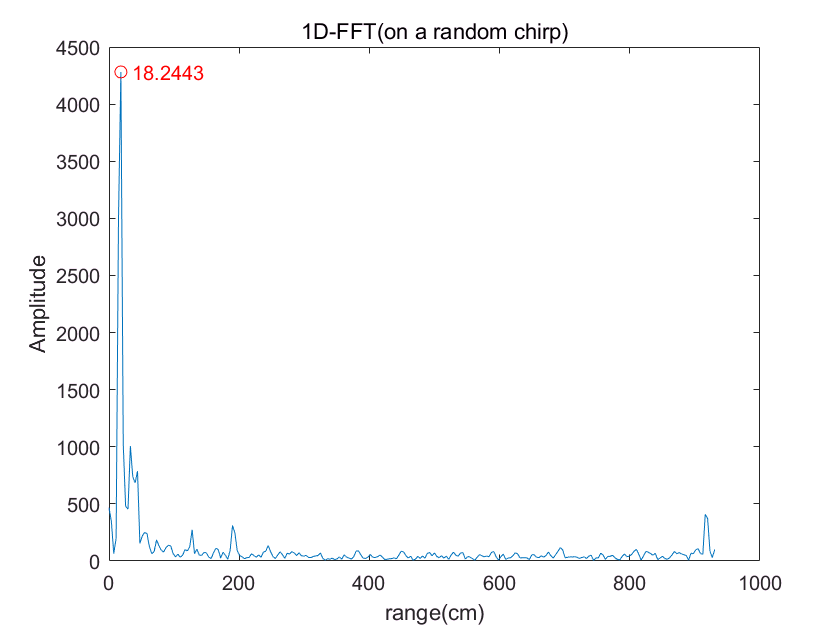

% n=chirpLoop/2:chirpLoop:length(Data1filtOut);
IF_mat=Data1filtOut;
[N,M]=size(IF_mat); %N为每chirp采样点，M为chirp数

%% 生成窗
range_win = hamming(N);  %生成range窗

%% range fft
for i = 1:1:M
    temp = IF_mat(:,i) .* range_win;
    temp_fft = fft(temp,N);
    IF_mat(:,i) = temp_fft;
%     IF_mat(:,i)=temp_fft-mean(temp_fft); %平均相消法滤除杂波
end

%找range-bin
% range_bin=(0:N-1)*c*Fs/N/2/k*100; %转换为cm
range_bin=(0:N-1)*c*Fs/N/2/k*100; %转换为cm
time=linspace(0,M*Periodicity,M);
[Val,Locs]=max(abs(IF_mat));
[Locs,ord]=mode(Locs); %众数，频次
% range_bin(Locs)

% 某chirp的1D-fft图
for i = 1:1:M
    [a,b]=max(abs(IF_mat(:,i)));
    if b==Locs
       example_chirp=b;
       example_Val=a;
       break
    end
end
figure;
plot(range_bin, abs(IF_mat(:,i))); %abs
text(range_bin(example_chirp),example_Val,['  ',num2str(range_bin(example_chirp))],'Color','red'); %]
hold on
plot(range_bin(example_chirp),example_Val,'ro');
title('1D-FFT(on a random chirp)');
ylabel('Amplitude'); 
xlabel('range(cm)');

%慢时间采样：Locs代表每个chirp取第Locs个采样点的数据。
% n=chirpLoop/2:chirpLoop:length(Data1filtOut);
Data_tmp=Data1filtOut;
Data_tmp = reshape(Data_tmp(Locs, :), [], 1);
% Data_tmp=Data_tmp(1:1024);
data_num=length(Data_tmp);

% %IQ不平衡补偿
% %求均值
% I_before_correction = real(Data_tmp)-mean(real(Data_tmp));
% Q_before_correction = imag(Data_tmp)-mean(imag(Data_tmp));
% 
% %估计参数
% e = sqrt(mean(Q_before_correction.*Q_before_correction)/mean(I_before_correction.*I_before_correction))-1;
% phi = -asin(mean(I_before_correction.*Q_before_correction)/sqrt(mean(I_before_correction.*I_before_correction)*mean(Q_before_correction.*Q_before_correction)));
% %P矩阵求解
% P = [1,0;tan(phi),1/((1+e)*cos(phi))];
% 
% %计算IQ
% for i=1:length(I_before_correction)
% IQ(:,i) = P*[I_before_correction(i);Q_before_correction(i)];
% end
% %重组信号
% I =IQ(1,:);
% Q =IQ(2,:);
% signal_IQ = I+Q*1j;
% figure();
% pwelch(signal_IQ,  [],[],[],fs);title('Spectrum at Rx baseband after I/Q correction');

% 不考虑IQ不平衡
I =real(Data_tmp);
Q =imag(Data_tmp);
signal_IQ = I+Q*1j;
% %图形绘制
% t=linspace(0,length(I)/fs,length(I));
% plot(t,I)
% % ylim([-2,2])
% title('不平衡补偿后的I');
% plot(t,Q)
% % ylim([-2,2])
% title('不平衡补偿后的Q');

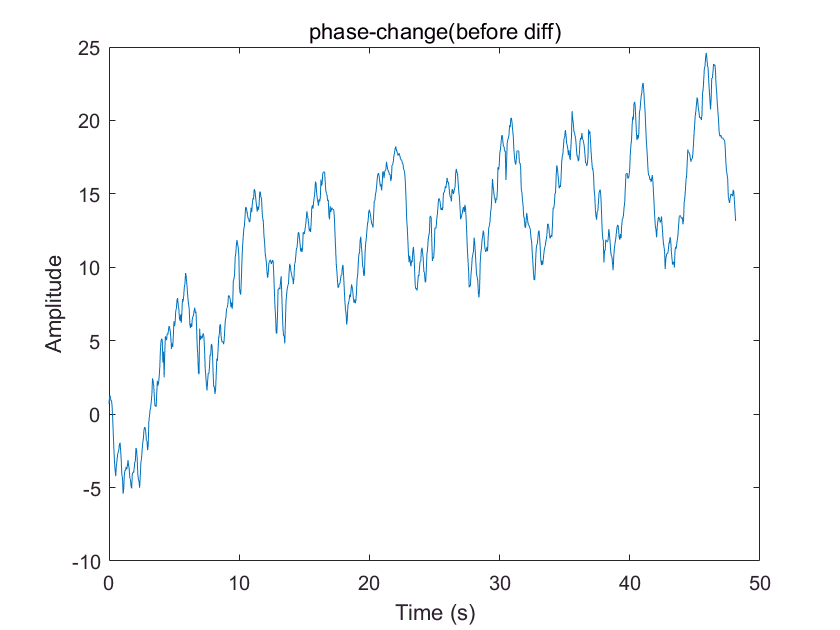

%相位提取和解缠绕
angle_data=angle(signal_IQ);
angle_data=unwrap(angle_data);
%线性去趋势
% angle_data = detrend(angle_data);
% %转置
% angle_data=angle_data'; 
% angle_data=(angle_data-mean(angle_data));
t=linspace(0,data_num*Periodicity,data_num);
figure;
plot(t, angle_data);
xlabel('Time (s)'); 
ylabel('Amplitude'); 
title('phase-change(before diff)');

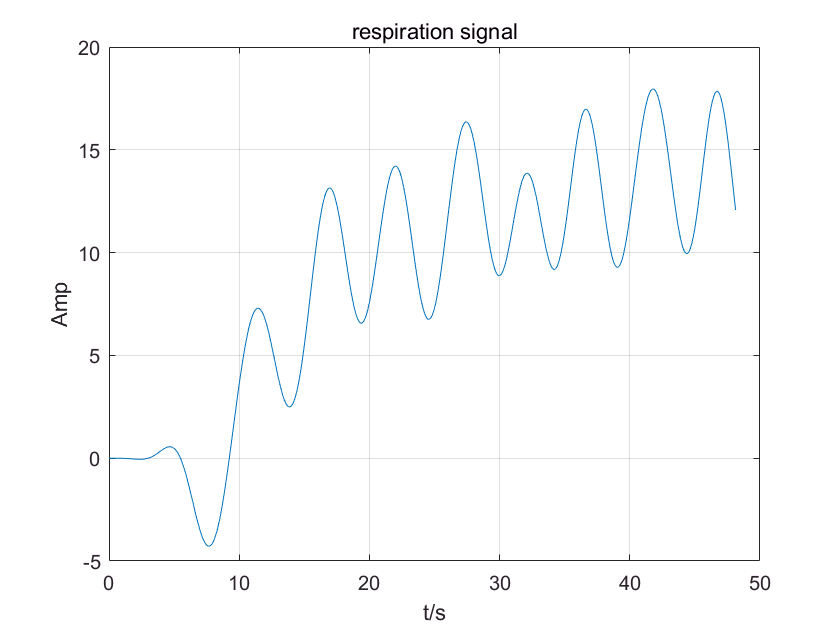

%低通滤波出呼吸信号
hd = lowpass;      % 根据自动生成滤波器的脚本文件名进行修改
[b,a]=tf(hd);            % 调用生成的滤波器
% [H,W]=freqz(b,a);        % 数字滤波器系统函数
% mag=abs(H);   % Amplitude
% % db=20*log10((mag+eps)/max(mag));% convert to dB
% db=20*log10(mag);% convert to dB
% pha=angle(H); % Phase
%  
% % f2=W*fs/(2*pi)/(1e3); % convert to MHz units
% f2=W*fs/(2*pi); % convert to MHz units
% % notice：上述转换成频率公式中的1e4为生成滤波器时的采样频率
% figure()
% subplot(2,1,1);plot(f2,db);
% title('Amplitude-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Amplitude（dB）');
% xlim([0,2]);
% subplot(2,1,2);plot(f2,pha);
% title('Phase-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Phase（rad）');
% xlim([0,2]);
% 

figure()
respiration=filter(b,a,angle_data);
t=linspace(0,length(respiration)/fs,length(respiration));
plot(t,respiration);grid on;
title('respiration signal');
xlabel ('t/s');
ylabel ('Amp');

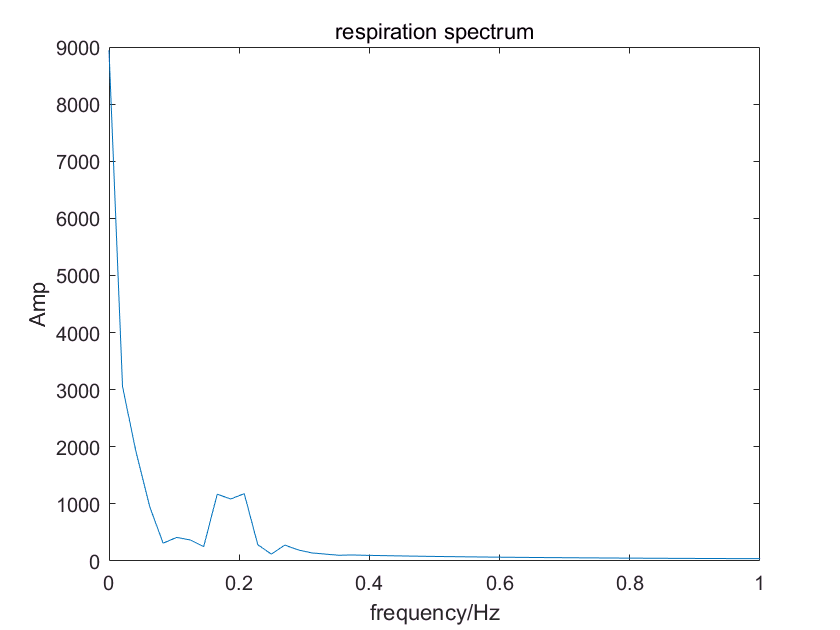

% xlim([10,20])

L=length(respiration);
respiration1=fftshift(fft(respiration));
ff=(-L/2:L/2-1)*fs/L;
plot(ff,abs(respiration1));
xlim([0,1]);
xlabel('frequency/Hz');
ylabel('Amp');
title ('respiration spectrum');

[Val,Locs]=findpeaks(abs(respiration1),'minpeakheight',-5);
for i = 1:1:length(Locs)
    if ff(Locs(i))>0.16
        if ff(Locs(i))<0.3
            fprintf ('The heartbeat frequency is %.2f Hz',ff(Locs(i)));
        end
    end
end

The heartbeat frequency is 0.17 HzThe heartbeat frequency is 0.21 HzThe heartbeat frequency is 0.27 Hz

hd = bandpass1416_21;      % 根据自动生成滤波器的脚本文件名进行修改
[b,a]=tf(hd);            % 调用生成的滤波器

x=angle_data;
t=linspace(0,length(angle_data)/fs,length(angle_data));
L=length(x);
x1=fftshift(fft(x));
ff=(-L/2:L/2-1)*fs/L;


bb=b;aa=a;
y_equi=filter(bb,aa,x); % 模拟输出 equiripple
y_equi1=fftshift(fft(y_equi));




hd = bandpass1416kaiser_21;      % 根据自动生成滤波器的脚本文件名进行修改
[b1,a1]=tf(hd);            % 调用生成的滤波器

bb=b1;aa=a1;
y_window=filter(bb,aa,x); % 模拟输出 window
y_window1=fftshift(fft(y_window));

hd = bandpass1416leastsquares2_21;      % 根据自动生成滤波器的脚本文件名进行修改

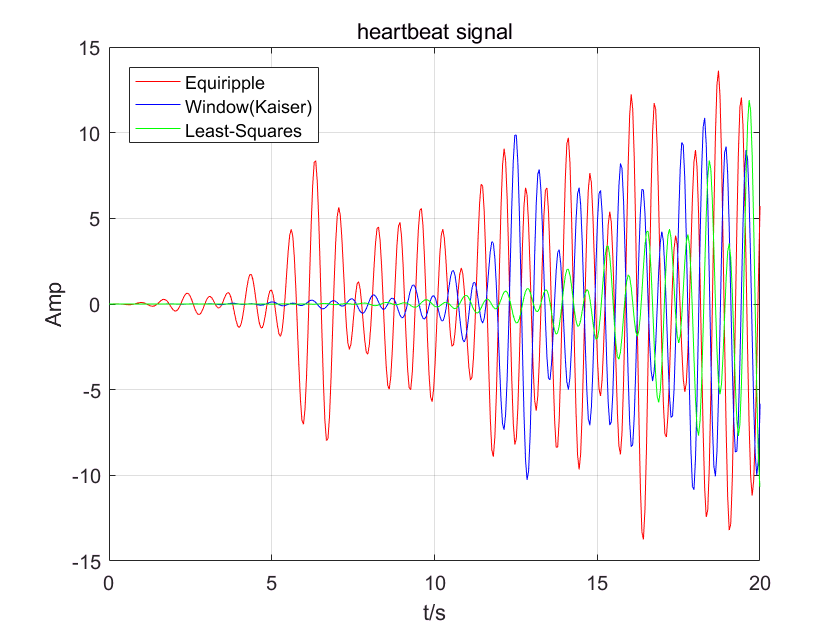

[b2,a2]=tf(hd);            % 调用生成的滤波器

bb=b2;aa=a2;
y_LeastSquares=filter(bb,aa,x); % 模拟输出 LeastSquares
y_LeastSquares1=fftshift(fft(y_LeastSquares));
figure()
plot(t,y_equi*8,'r-',t,y_window*8,'b-',t,y_LeastSquares*65,'g-');grid on;
legend('Equiripple','Window(Kaiser)','Least-Squares','Location','NorthWest');
xlabel ('t/s');
ylabel ('Amp');
title('heartbeat signal');
xlim([0,20]);

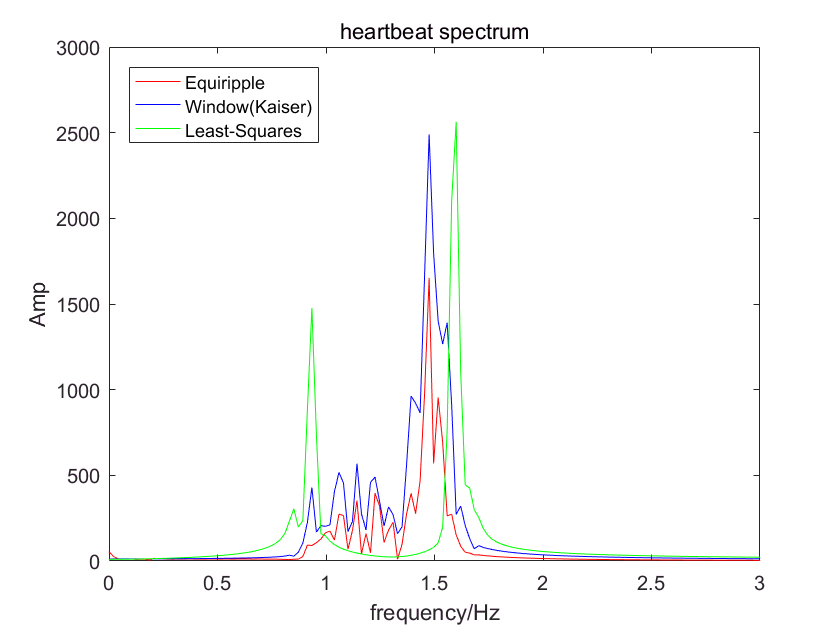

figure()
plot(ff,abs(y_equi1)*5,'r-',ff,abs(y_window1)*10,'b-',ff,abs(y_LeastSquares1)*25,'g-');
legend('Equiripple','Window(Kaiser)','Least-Squares','Location','NorthWest');
xlabel('frequency/Hz');
ylabel('Amp');
title ('heartbeat spectrum');
xlim([0,3]);

[Val,Locs]=max(abs(y_equi1));
fprintf ('The heartbeat frequency is %.2f Hz',-ff(Locs));

The heartbeat frequency is 1.48 Hz

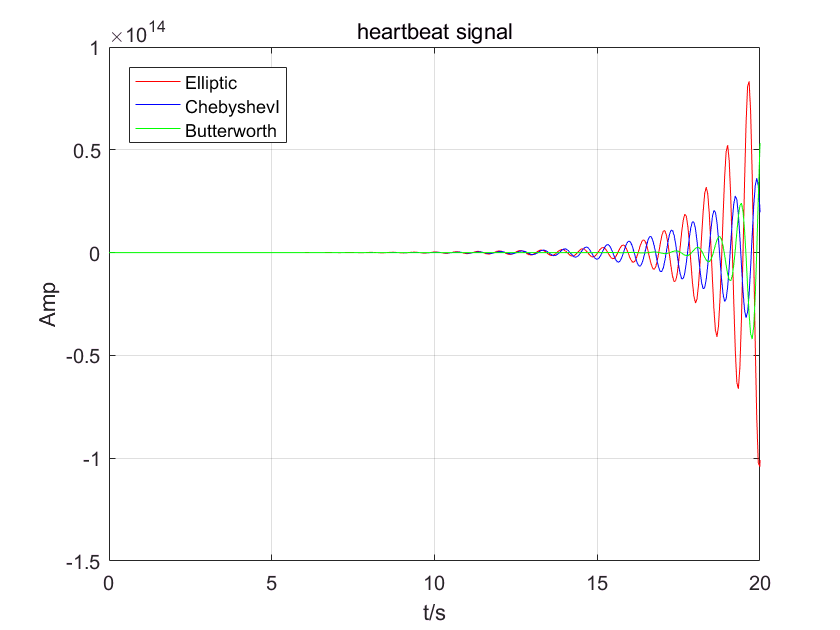

% iir滤波器
% f_s1     =   1.6     ;   %阻带上截止频率
% f_s2    =  1.9;
% f_p1    =   1.7     ;   %通带下截止频率
% f_p2    =   1.8;
f_s1     =   1.3     ;   %阻带上截止频率
f_s2    =  1.7;
f_p1    =   1.4     ;   %通带下截止频率
f_p2    =   1.6;

R_p     =   0.5       ;   %通带允许的最大衰减
R_s    =   40     ;   %阻带允许的最小衰减
f_s     =   21    ;   %采样频率
T_s     =   1 / f_s ;   %采样间隔
%1.将数字高通滤波器的频率参数变换为归一化的数字角频率参数
omega_p1  = 2 * pi * f_p1  /f_s;
omega_s1 = 2 * pi * f_s1 /f_s;
omega_p2  = 2 * pi * f_p2  /f_s;
omega_s2 = 2 * pi * f_s2 /f_s;
%2.预畸变处理,将归一化数字角频率参数变换成模拟高通滤波器的角频率参数
C = 2 / T_s ;
Omega_p1   =C*tan( omega_p1  / 2 );
Omega_s1  = C*tan( omega_s1 / 2 ); 
Omega_p2   = C*tan( omega_p2  / 2 );
Omega_s2  = C*tan( omega_s2 / 2 );
W0=sqrt(Omega_p1*Omega_p2);
Omega_BW=Omega_p1-Omega_p2;
%3.对模拟高通滤波器的角频率参数做归一化处理
eta_sl      =   Omega_s1 / Omega_BW;
eta_p1       =   Omega_p1  / Omega_BW;   
eta_p2       =   Omega_p2  / Omega_BW;
eta_s2      =   Omega_s2 / Omega_BW;
%4.设计归一化模拟滤波器,得到归一化模拟高通滤波器的转移函数
wph=[Omega_p1,Omega_p2 ];
wsh=[Omega_s1,Omega_s2];
[ N1 , Wn1 ] = buttord( wph , wsh , R_p , R_s , 's' ); %选择模拟巴特沃斯滤波器的最小阶数

[N2,Wn2]=cheb1ord(wph,wsh,R_p,R_s,'s');       %求切比雪夫I型滤波器阶数
% [N,Wn]=cheb2ord(wph,wsh,R_p,R_s,'s');       %求切比雪夫II型滤波器阶数
[N3,Wn3]=ellipord(wph,wsh,R_p,R_s,'s');        %求椭圆型滤波器阶数

[ z1 , p1 , k1 ] = buttap(N1); %创建巴特沃斯模拟低通滤波器
[ z2 , p2 , k2 ] = buttap(N2); %创建切比雪夫模拟低通滤波器
[ z3 , p3 , k3 ] = buttap(N3); %创建椭圆型模拟低通滤波器
%[ Bp , Ap ] = zp2tf(z,p,k); %由零点、极点、增益确定传输函数的分子与分母系数
%5.利用归一化模拟高通滤波器的转移函数确定模拟高通滤波器的转移函数
BB1=real(poly(z1));
AA1=real(poly(p1));
[ b1 , a1 ] = lp2bp(BB1,AA1,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz1 , az1 ] = bilinear(b1,a1,f_s);

BB2=real(poly(z2));
AA2=real(poly(p2));
[ b2 , a2 ] = lp2bp(BB2,AA2,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz2, az2 ] = bilinear(b2,a2,f_s);

BB3=real(poly(z3));
AA3=real(poly(p3));
[ b3 , a3 ] = lp2bp(BB3,AA3,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz3 , az3 ] = bilinear(b3,a3,f_s);
% figure(1);
% freqz(bz,az);
% title('filter characteristic curve');


% bb=b;aa=a;

% [H,W]=freqz(bz3,az3);        % 数字滤波器系统函数
% mag=abs(H);   % Amplitude
% % db=20*log10((mag+eps)/max(mag));% convert to dB
% db=20*log10(mag);% convert to dB
% pha=angle(H); % Phase
%  
% % f2=W*fs/(2*pi)/(1e3); % convert to MHz units
% f2=W*fs/(2*pi); % convert to MHz units
% % notice：上述转换成频率公式中的1e4为生成滤波器时的采样频率
% figure()
% subplot(2,1,1);plot(f2,db);
% title('Amplitude-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Amplitude（dB）');
% xlim([0,3]);
% subplot(2,1,2);plot(f2,pha);
% title('Phase-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Phase（rad）');
% xlim([0,3]);


x=angle_data;
t=linspace(0,length(angle_data)/fs,length(angle_data));
L=length(x);
x1=fftshift(fft(x));
ff=(-L/2:L/2-1)*fs/L;

bb=bz1;aa=az1; %数字iir
y_butterworth=filter(bb,aa,x); % 模拟输出
y_butterworth1=fftshift(fft(y_butterworth));

bb=bz2;aa=az2; %数字iir
y_cheb1ord=filter(bb,aa,x); % 模拟输出
y_cheb1ord1=fftshift(fft(y_cheb1ord));

bb=bz3;aa=az3; %数字iir
y_ellipord=filter(bb,aa,x); % 模拟输出
y_ellipord1=fftshift(fft(y_ellipord));

figure()
plot(t,y_ellipord*300000000,'r-',t,y_cheb1ord*50000000,'b-',t,y_butterworth,'g-');grid on;
legend('Elliptic','ChebyshevI','Butterworth','Location','NorthWest');
xlabel ('t/s');
ylabel ('Amp');
title('heartbeat signal');
xlim([0,20])

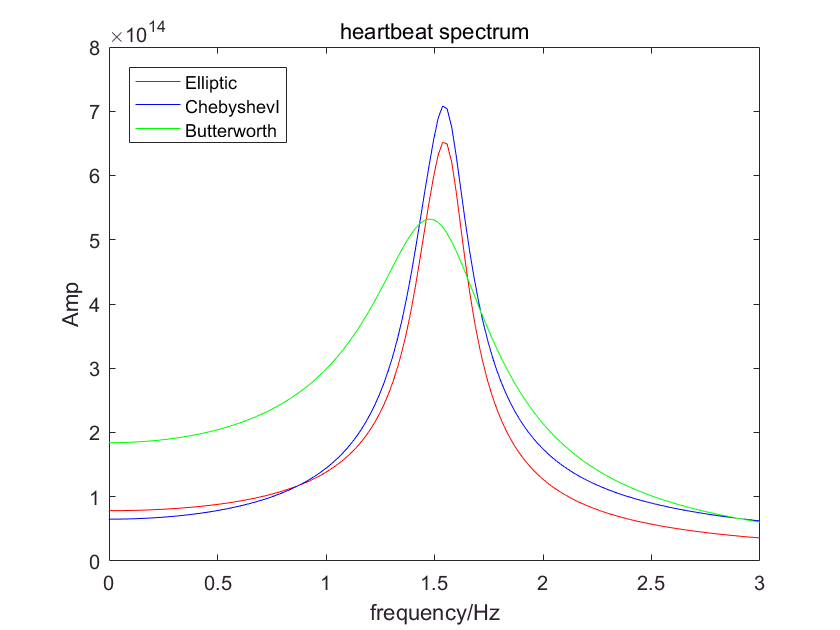

figure()
plot(ff,abs(y_ellipord1)*5,'r-',ff,abs(y_cheb1ord1),'b-',ff,abs(y_butterworth1)/200000000000000000000,'g-');
legend('Elliptic','ChebyshevI','Butterworth','Location','NorthWest');
xlabel('frequency/Hz');
ylabel('Amp');
title ('heartbeat spectrum');
xlim([0,3]);

[Val,Locs]=max(abs(y_ellipord1));
fprintf ('The heartbeat frequency is %.2f Hz',-ff(Locs));

The heartbeat frequency is 1.54 Hz

% plot(t,y_ellipord);grid on;
% title('heart signal');
% xlabel ('t/s');
% ylabel ('Amp');
% xlim([10,20])
% figure(2)
% subplot(2,2,1)
% plot(t,x);
% xlabel ('(a)输入信号');
% subplot(2,2,2)
% plot(ff,abs(x1));
% xlabel ('(b)输入信号频谱');
% xlim([0,3])
% subplot(2,2,3)
% plot(t,y);grid on;
% xlabel('(c)输出信号');
% subplot(2,2,4)
% plot(ff,abs(y1));
% xlabel ('(d)输出信号频谱');
% xlim([0,3])